clear
close all
clc


% load コマンド
load DemoDataSJ



# **データのロード：　スクワットジャンプの際の床反力と動作データ**

Current directory の mat ファイルをダブルクリック　または、load コマンドを実行する

ワークスペースに、変数（ grfs, Markers ） があることを確認

% load コマンド
load DemoDataSJ

% 関数として実行
fileName = 'DemoDataSJ' ;
load(fileName) ;



# **データをプロットする**

１．変数エディタで変数の中身を確認する

変数　grfs には、床反力のデータが格納されている。

ワークスペースから、変数をダブルクリックすると、変数エディタが開かれ、データが見える（2次元数値配列なので、Excelで見たことある感じ）

1~3列目が、左足 fx, fy, fz 、4~6列目が、右足  fx, fy, fz 　

２．Excel っぽく、マウスクリックでプロット

ワークスペースから、変数をダブルクリック、変数エディタから列を選択→プロットタブから時系列グラフを選択

教科書で見たことがあるような、垂直跳びの床反力波形が確認できる

※　正の値は、身体を上方向に加速させる力である

※　足が地面から離れた状態では、フォースプレートが観測する値は 0 である

※　縦軸は、体重で正規化した値であることに注意

※　左足と右足、ほぼ均等に体重がかかっているので、静止状態では、おおよそ 0.5 となっている

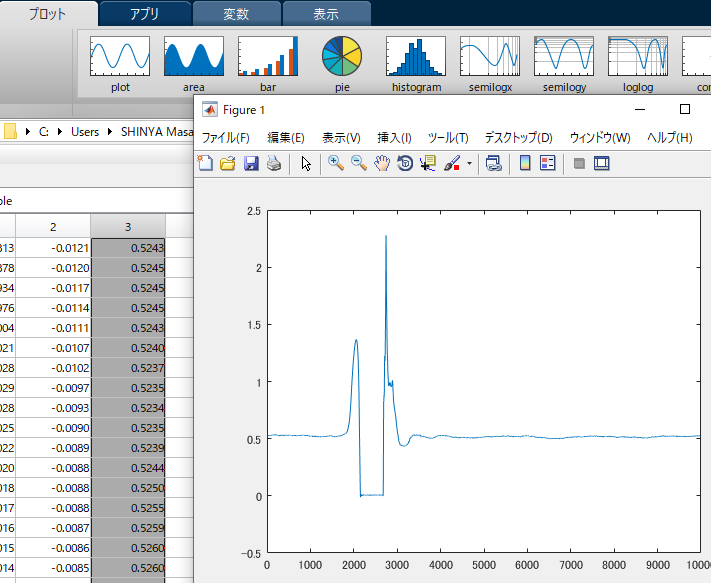

３．プロットするためのプログラムを書く

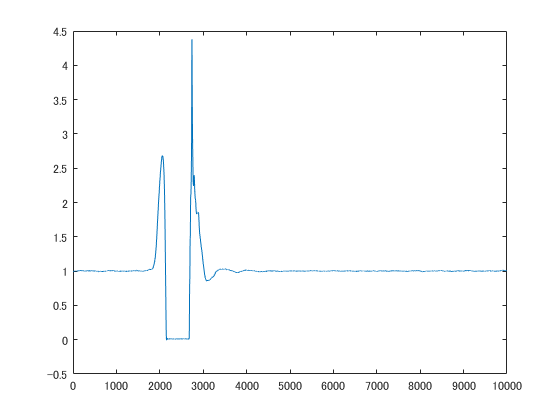

close all % 既に作成されているプロットがあれば削除

fzL = grfs(:,3) ; % 3列目は、左足が受けた床反力
fzR = grfs(:,6) ; % 6列目は、右足が受けた床反力
fz = fzL + fzR ;  % 左右の床反力を足して、身体が地面から受けた床反力

plot(fz)

４．ちょっと凝ったプロット

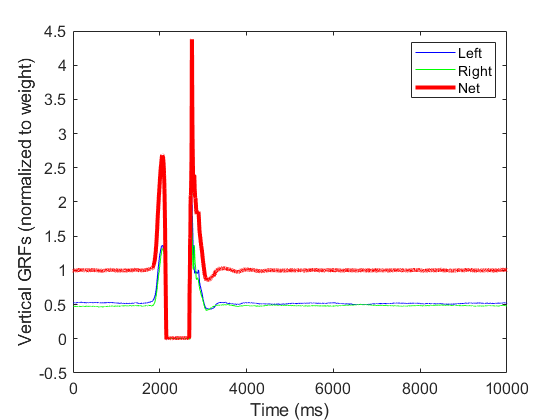

figure
plot(fzL, 'b-') ; hold on % hold on コマンドで、複数のプロットを同じ図に書き込める
plot(fzR, 'g-')
plot(fz, 'r', 'linewidth', 3)
legend({'Left', 'Right', 'Net'})
xlabel('Time (ms)')
ylabel('Vertical GRFs (normalized to weight)')
set(gca, 'fontsize', 12, 'fontname', 'arial')